

% __mini_funcio__ Determinar píxels

% Donada una imatge inicial, es determina l'escala d'aquesta de manera
% interactiva, ja sigui introduïnt el valor de l'escala o bé
% determinant-lo per la imatge.

% variables:
% input: imatge inicial
% interactiu: introduccio escala ; si/no{imatge seleccio cropping}
% output: escala imatge

% 'clau' per a sortir del while, quan tot estigui correcte. Sinó es torna a
% introduïr les dades.
corrector_tot_be = 1 %<- true

corrector_tot_be = 1

answer = 'Introduir numeric'

corrector_tot_be_numeric = 1

answer = 1×1 cell array
    {'56'}


answer2 = 56

corrector_tot_be_numeric = 0

answer = 'Introduir numeric'

corrector_tot_be_numeric = 1

answer = 1×1 cell array
    {'34'}


answer2 = 34

corrector_tot_be_numeric = 0

answer = 'Introduir numeric'

corrector_tot_be_numeric = 1

answer = 1×1 cell array
    {'fd32'}



answer2 =

     []



corrector_tot_be_numeric = 0

has seleccionat: Seleccionar en imatge


answer = 'Seleccionar en imatge'

NUMERIC


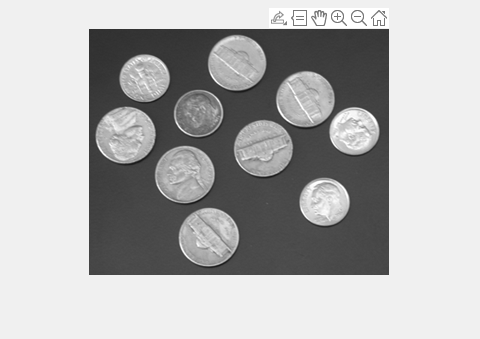

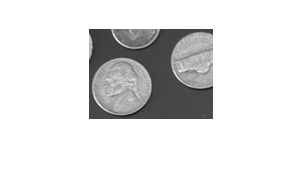


while corrector_tot_be

    answer = questdlg('Introdueix la escala', ...
    	'Escala', ...
    	'Seleccionar en imatge','Introduir numeric','Introduir numeric');
    % Handle response
    switch answer
        case 'Seleccionar en imatge'
            disp("has seleccionat: Seleccionar en imatge")
        case 'Valor numeric'
            disp('has seleccionat: Valor numeric')
    end
    
    answer
    
    if answer == "Introduir numeric"
        
        corrector_tot_be_numeric = 1 %<- true, no surt del bloc.
        while corrector_tot_be_numeric
            
            prompt = {'Enter matrix size:'};
            dlgtitle = 'Input';
            dims = [1 25];
            definput = {''};
            answer = inputdlg(prompt,dlgtitle,dims,definput)
            
            answer2 = str2num(answer{1})
            
            waitfor(msgbox('Invalid Value', 'Error','error'));
            
            corrector_tot_be_numeric = 0;
            corrector_tot_be_numeric

            
        end

    end
    
    if answer == "Seleccionar en imatge"
        disp("NUMERIC")
        
        % Selecció per crop:
        I = imread('coins.png');
        [I2,rect] = imcrop(I);
        figure, imshow(I2)
        
        % Llavors esqueletonització
        corrector_tot_be = 0;
    
    end

end